addpath('functions/');

% Parameters for zero-mean normal distribution
std_dev = 0.04;
mean = 0;

v_is = std_dev.*randn(30000, 2000) + mean;

% Initalize the base CS cells
x_0 = -1 + (1+1)*rand(1, 2000);

normal_therapy = normal_therapy();
add_acute_dose = add_acute_dose();
add_chronic_dose = add_chronic_dose();

% Creating Patients' Corticalspinal cells.
% Patient 1 - Severely Impaired
n_1 = 1000;

normal_therapy_forces_1 = get_final_forces(x_0(1:n_1), v_is, normal_therapy, n_1);

trial_count = 11526

add_acute_dose_forces_1 = get_final_forces(x_0(1:n_1), v_is, add_acute_dose, n_1);

trial_count = 20976

add_chronic_dose_forces_1 = get_final_forces(x_0(1:n_1), v_is, add_chronic_dose, n_1);

trial_count = 20556


plot(normal_therapy_forces_1, '-', 'Color', 'red')
hold on
plot(add_acute_dose_forces_1, ':', 'Color', 'red')
hold on 
plot(add_chronic_dose_forces_1, '--', 'Color', 'red')
hold on
% Patient 2 - moderately Impaired
n_2 = 2000;

normal_therapy_forces_2 = get_final_forces(x_0(1:n_2), v_is, normal_therapy, n_2);

trial_count = 11526

add_acute_dose_forces_2 = get_final_forces(x_0(1:n_2), v_is, add_acute_dose, n_2);

trial_count = 20976

add_chronic_dose_forces_2 = get_final_forces(x_0(1:n_2), v_is, add_chronic_dose, n_2);

trial_count = 20556


plot(normal_therapy_forces_2, '-', 'Color', 'blue')
hold on 
plot(add_acute_dose_forces_2, ':', 'Color', 'blue')
hold on 
plot(add_chronic_dose_forces_2, '--', 'Color', 'blue')
hold off

% Create graph parameters
title("Force Recovery VS Day")
% ylim([0, 1000])
xlim([0, 600])
ylabel('Force')
xlabel('Day')


% saveas(gcf,'images/ForceRecoveryVSDay.png')

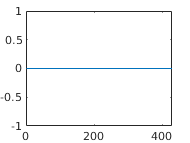

plot(add_acute_dose_forces_1)

Create forces with different rehabilitation methods (r_method) and n CS cells

function final_forces = get_final_forces(x_0, v_is, r_method, n)
    % CS extensor and flexor connection weights
    c_fi = ones(1, n);
    
    agonist = randperm(n * 0.99);

    % Translating MN pool to force
    delta = 1;
    
    final_forces = [];
    f_final_net = 0;

    trial_count = 1;
    for day_i = 1:length(r_method)
        day = r_method(day_i);
        for trial = 1:day
            v_i = v_is(trial_count, 1:n);
            x_i = x_0 + v_i;
            
            s_fi = 0;
            % Facilitate
            for i = 1:length(agonist)
                ind = agonist(i);
                temp = g_fi(x_i(ind), c_fi(ind));
                s_fi = s_fi + temp;
            end
            f_f = delta * s_fi;
        
            % Net force
            f_net = f_f;
        
            if f_net > f_final_net
                f_final_net = f_net;
                x_0 = x_i;
            end

            trial_count = trial_count + 1;
        end
        % days = [days, day_i];
        % forces = [forces, f_net];
        final_forces = [final_forces, f_final_net];
    end
end